# Examples for using the `newtons_method` function.

Copyright © 2021 Tamas Kis

## Example #1: Root of a simple function.

*Find the root of *$f\left(x\right)=x^2 -1$ *that is in the interval *$\left\lbrack 0,\infty \right)$.

For Newton's method, we also need $f^{\prime } \left(x\right)$. Differentiating $f\left(x\right)$,

                    
$$f^{\prime } \left(x\right)=2x$$


Defining $f\left(x\right)$ and $f^{\prime } \left(x\right)$ in MATLAB,

f = @(x) x^2-1;
df = @(x) 2*x;

We want a root in the interval $\left\lbrack 0,\infty \right)$. Therefore, we use the initial guess $x_0 =10$. Finding this root using Newton's method,

x = newtons_method(f,df,10)

x = 1

## Example #2: Plot of root estimates at each iteration.

*In Example #1, we found the positive root of *$f\left(x\right)=x^2 -1$* using Newton's method. Now, produce a plot of all root estimates obtained by the *`newtons_method`* function during its solution procedure.*

First, we define $f\left(x\right)$ and $f^{\prime } \left(x\right)$ in MATLAB like before.

f = @(x) x^2-1;
df = @(x) 2*x;

To obtain the root estimates at all iterations, we simply need to define the `opts` structure, set its `return_all` field to `true`, and pass it to the `newtons_method` function. *(Note: we use the same initial guess as in Example #1).*

opts.return_all = true;
[~,~,x_all] = newtons_method(f,df,10,opts);

Plotting the root estimates at each iteration,

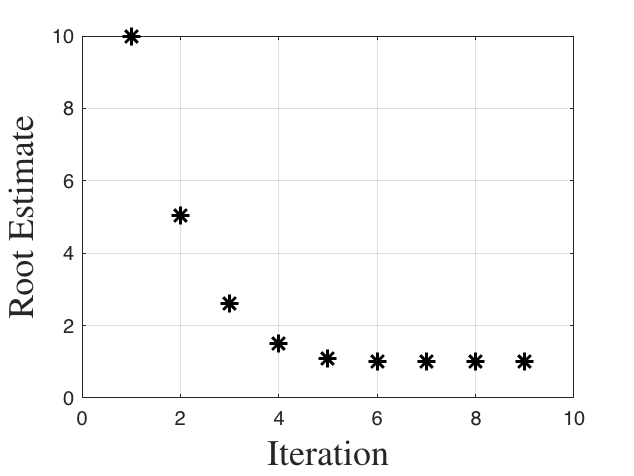

figure;
plot(x_all,'k*','MarkerSize',9,'LineWidth',1.5);
grid on;
xlabel('Iteration','Interpreter','latex','FontSize',18);
ylabel('Root Estimate','Interpreter','latex','FontSize',18);

## Example #3: Intersection of two curves.

*Find the intersection of *$y=x^2$ and $y=\cos \left(x\right)$ *that is in the interval *$\left\lbrack 0,\infty \right)$.

Defining both functions and their derivatives,

% y = x^2 and its derivative
y1 = @(x) x.^2;
dy1 = @(x) 2.*x;

% y = cos(x) and its derivative
y2 = @(x) cos(x);
dy2 = @(x) -sin(x);

Let's plot both functions to see where their intersection lies.

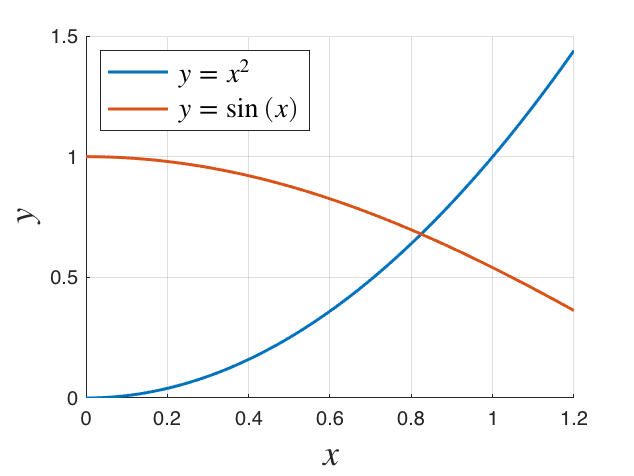

% defines interval for plotting
x = 0:0.01:1.2;

% plot
figure;
hold on;
plot(x,y1(x),'LineWidth',1.5);
plot(x,y2(x),'LineWidth',1.5);
hold off;
grid on;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
legend('$y=x^{2}$','$y=\sin{(x)}$','Interpreter','latex','FontSize',14,...
    'Location','northwest');

Finding the intersection of the two functions is equivalent to finding the *root* of their difference. Therefore, we can use Newton's method on $y=\cos \left(x\right)-x^2$ with an initial guess of $x_0 =0\ldotp 8$ (picked using the plot above) to find the intersection.

x_int = newtons_method(@(x) y2(x)-y1(x),@(x) dy2(x)-dy1(x),0.8)

x_int = 0.8241

Plotting to confirm that this is the true intersection,

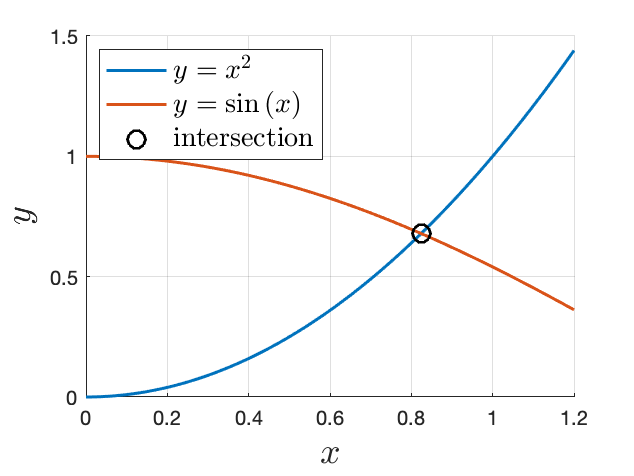

figure;
hold on;
plot(x,y1(x),'LineWidth',1.5);
plot(x,y2(x),'LineWidth',1.5);
plot(x_int,y1(x_int),'ko','MarkerSize',9,'LineWidth',1.5);
hold off;
grid on;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
legend('$y=x^{2}$','$y=\sin{(x)}$','intersection','Interpreter','latex',...
    'FontSize',14,'Location','northwest');